clear all

% Radar Toolbox Implementation
% 参数设置
c = physconst('LightSpeed'); % 光速
f = 10e8;                  % 雷达频率 (Hz)
lambda = c / f;            % 波长 (m)
num_drones = 8;             % 无人机数量（阵元数）
d = lambda / 2;             % 阵元间距 (m)
x_positions = (-(num_drones-1)/2 : (num_drones-1)/2) * d; % 无人机x轴位置
y_velocity = 5;             % 无人机y轴速度 (m/s)
simulation_time = 10;       % 仿真时间 (秒)
time_step = 0.1;            % 时间步长 (秒)
theta_scan = 0:1:180;      % 扫描角度范围，限制到前半圆


% 时间序列
time = 0:time_step:simulation_time;

% 模拟动态目标方向
theta_target = 60 * sin(2 * pi * 0.1 * time)+90; % 动态目标方向随时间变化

% 初始化变量
element_positions = zeros(3, num_drones); % 初始位置，3行表示X、Y、Z坐标
element_positions(1, :) = x_positions;   % 固定X坐标
array_factors = zeros(length(time), length(theta_scan)); % 存储每个时刻的阵列因子
detected_targets = zeros(1, length(time)); % 存储检测到的目标方向

% 创建雷达场景
scene = radarScenario('UpdateRate', 1/time_step, 'StopTime', simulation_time);

% 添加动态目标
platform_target = platform(scene);
platform_target.Trajectory = waypointTrajectory('Waypoints', [100 0 0; 1000 500 0], 'TimeOfArrival', [0 simulation_time]);
platform_target.Dimensions = struct('Length', 5, 'Width', 5, 'Height', 2, 'OriginOffset', [0 0 0]);

% 添加雷达平台
radar_platform = platform(scene);
radar_platform.Trajectory = kinematicTrajectory('Velocity', [0 y_velocity 0]);
radar_platform.Dimensions = struct('Length', 5, 'Width', 5, 'Height', 2, 'OriginOffset', [0 0 0]);
radar_sensor = radarDataGenerator('SensorIndex', 1, 'UpdateRate', 1/time_step, ...
    'MountingLocation', [0 0 0], 'DetectionMode', 'Monostatic', ...
    'AzimuthResolution', 1, 'RangeResolution', 10);
radar_platform.Sensors = {radar_sensor};

% 动态波束扫描
for t = 1:length(time)
    % 动态更新阵列位置
    element_positions(2, :) = y_velocity * time(t); % 更新Y坐标
    dynamic_array = phased.ConformalArray('ElementPosition', element_positions); % 重建动态阵列

    % 计算波束方向增益
    sv = phased.SteeringVector('SensorArray', dynamic_array, 'PropagationSpeed', c);

    
    for i = 1:length(theta_scan)

        % 修正目标相位差，匹配坐标系方向
        target_phase_shift = -2 * pi / lambda * (element_positions(1, :) * cosd(theta_target(t)) + ...
                                                 element_positions(2, :) * sind(theta_target(t)));

        weights = sv(f, theta_scan(i)) .* exp(1j * target_phase_shift'); % 引入动态目标方向相位
        array_factors(t, i) = abs(sum(weights)); % 合成波束增益
    end

    % 归一化
    if max(array_factors(t, :)) > 0
        array_factors(t, :) = array_factors(t, :) / max(array_factors(t, :));
    end

    % 检测目标方向（只检测前半圆）
    [~, max_idx] = max(array_factors(t, :));
    detected_targets(t) = theta_scan(max_idx);

    % 更新场景
    advance(scene);
end

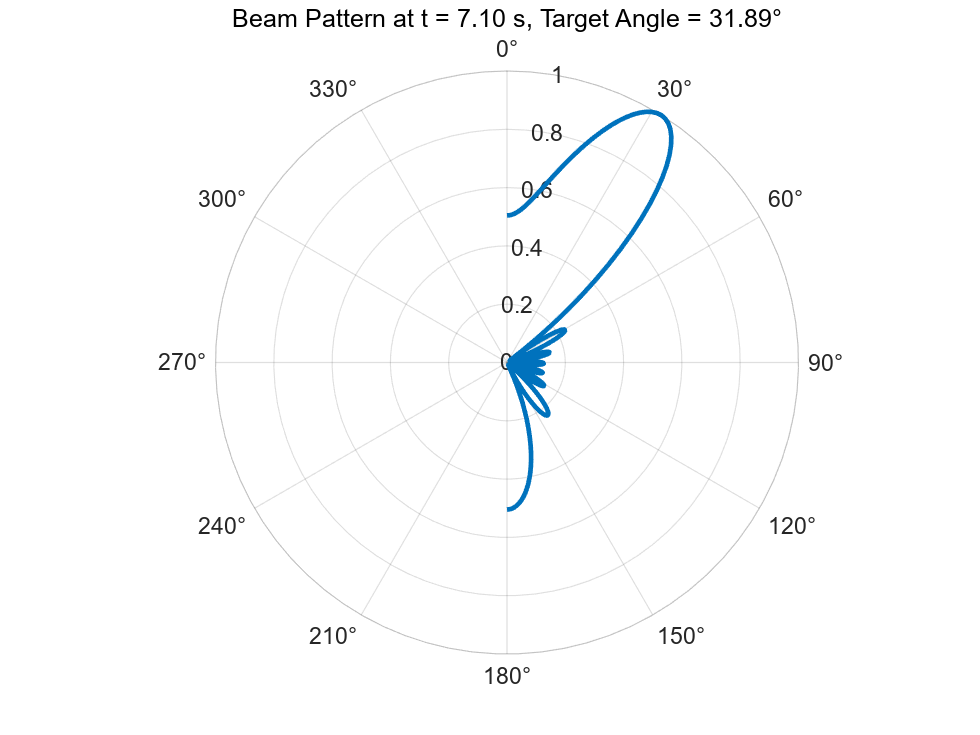


% 动态波束方向图动画
figure;
polarplot_handle = polarplot(deg2rad(theta_scan), array_factors(1, :), 'LineWidth', 2);
title('Dynamic Beam Pattern');
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.ThetaDir = 'clockwise';

for t = 1:length(time)
    polarplot_handle.ThetaData = deg2rad(theta_scan);
    polarplot_handle.RData = array_factors(t, :);
    title(sprintf('Beam Pattern at t = %.2f s, Target Angle = %.2f°', time(t), theta_target(t))); % 修正字符
    drawnow; % 强制刷新动画
    pause(0.05);
end


legend;
hold off;

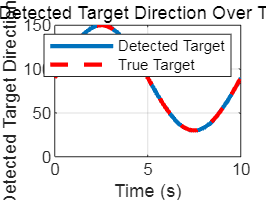


% 绘制检测到的目标方向随时间变化
figure;
plot(time, detected_targets, 'LineWidth', 2);
hold on;
plot(time, theta_target, 'r--', 'LineWidth', 2); % 添加真实目标方向
xlabel('Time (s)');
ylabel('Detected Target Direction (°)'); % 修正字符
title('Detected Target Direction Over Time');
legend('Detected Target', 'True Target');
grid on;

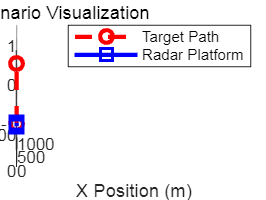



% 3D雷达场景可视化
figure;
hold on;
grid on;
title('3D Radar Scenario Visualization');
xlabel('X Position (m)');
ylabel('Y Position (m)');
zlabel('Z Position (m)');
view(3); % 设置3D视角

% 绘制目标轨迹
target_positions = platform_target.Trajectory.Waypoints;
plot3(target_positions(:, 1), target_positions(:, 2), target_positions(:, 3), 'r--o', 'LineWidth', 2, 'DisplayName', 'Target Path');

% 绘制雷达平台移动轨迹
radar_positions = [zeros(length(time), 1), y_velocity * time', zeros(length(time), 1)];
plot3(radar_positions(:, 1), radar_positions(:, 2), radar_positions(:, 3), 'b-s', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Radar Platform');

legend;
hold off;